# `Common ancestor behavioural repertoire reconstrcution`

`Reconstruction common ancestor behavioural repertoire following the work by Berman et al. (`[`Article`](https://doi.org/10.7554/eLife.61806)`). Part of the code is taken from the code `[`Behavioural space reconstruction`](matlab:open('../BehavouralSpaceReconstruction/Self_BehaviouralSpaceReconstruction.mlx'))`, implemented following Berman et al. method (`[`Article`](https://doi.org/10.1098/rsif.2014.0672)`). `

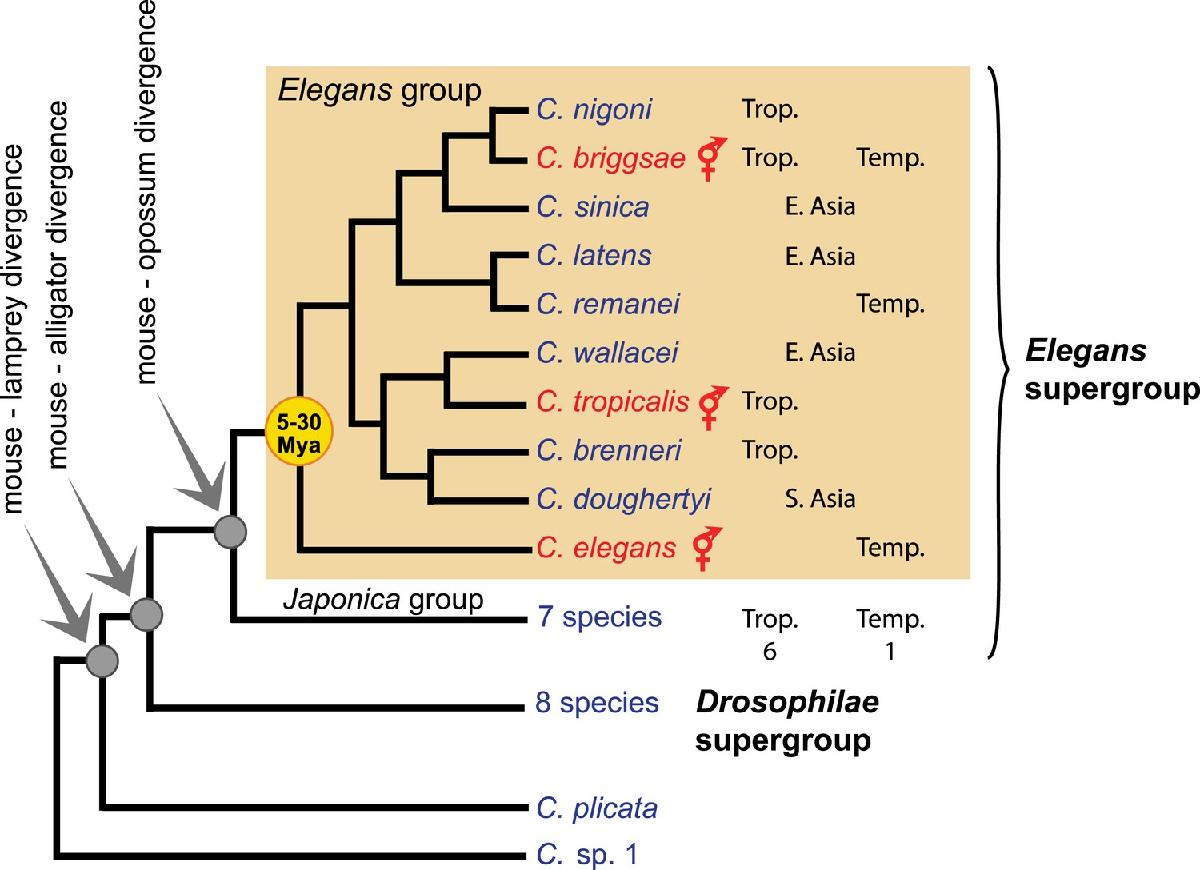

- General linear 

clear all; close all; clc;

#### 1. Load data from 7 strains, 3 species

Data taken from '/Volumes/gr-gnb-share/data/Serena/species' 

% to facilitate path definition 
n = 1;  % n = 0 "my Mac", n = 1 "office Mac"

switch n
    case 0
        cd '/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /Skeleton'
    case 1
        cd '/Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /Skeleton'
end 

fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile = fds.Files;

numFiles = length(skelFile);


% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);   
    fprintf('Now reading file %s\n', skelFile{k});

    trajData_struc.(name) = h5read(skelFile{k},'/trajectories_data');
    blobFeats_struc.(name) = h5read(skelFile{k},'/blob_features');
    skeleton_struc.(name)= h5read(skelFile{k}, '/skeleton');
end 

Now reading file /Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /Skeleton/metadata_skeletons816.hdf5
Now reading file /Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /Skeleton/metadata_skeletons818.hdf5




switch n
    case 0
        cd '/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /FeaturesN' 
    case 1
        cd '/Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /FeaturesN'
end 

fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

featuresFile = fds.Files;

numFiles = length(featuresFile);

% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);    
    fprintf('Now reading file %s\n', featuresFile{k});

    time_series.(name)= h5read(featuresFile{k}, '/timeseries_data');
end  

Now reading file /Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /FeaturesN/metadata_featuresN816.hdf5
Now reading file /Users/dinglab/Desktop/Briggsae and Tropicalis /Day 1 /FeaturesN/metadata_featuresN818.hdf5


cd('..')

switch n
    case 0
        cd('/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis ')
    case 1
        cd('/Users/dinglab/Desktop/Briggsae and Tropicalis ') 
end 



#### Seperate the index of the different strains. One cell entry per strain indexes

number_strains = 7; 
index_strain_i = cell(7,1);

% 818
letter_ind = ['A', 'B', 'C', 'D']';
groups_incl = ['1', '2', '3','4'];
name = sprintf('dataSet_%d', 2);
timeSeries2_cell = struct2cell(time_series.(name)); 
for i = 1:size(letter_ind,1) % loop through the letters 
    letter = letter_ind(i);
    for k=1:size(groups_incl,1)
        index_strain_i{i,1} = [index_strain_i{i,1}; find((timeSeries2_cell{3}(1,:) == letter) & (timeSeries2_cell{3}(2,:) == groups_incl(k)))']; 
    end 
end 

% 816
letter_ind = ['E','F','G']';
name = sprintf('dataSet_%d', 1);
timeSeries1_cell = struct2cell(time_series.(name)); 
for i = 1:size(letter_ind,1) % loop through the letters 
    letter = letter_ind(i);
    j = i+4;
    for k=1:size(groups_incl,1)
        index_strain_i{j,1} = [index_strain_i{i,1}; find((timeSeries1_cell{3}(1,:) == letter) & (timeSeries1_cell{3}(2,:) == groups_incl(k)))'];
    end 
end 

#### 2. Covariance Matrix 

Use all skeletons for covariance matrix. No need for strains and species seperation till after state space reconsturction 

x = []; y = []; 

v = [1 0];

for i=1:2 % loop through all the worms     
    name = sprintf('dataSet_%d', i);
    x_3D = skeleton_struc.(name)(1,:,:); 
    x = [x; reshape(x_3D,[49,size(skeleton_struc.(name),3)])'];
    y_3D = skeleton_struc.(name)(2,:,:); 
    y = [y; reshape(y_3D,[49,size(skeleton_struc.(name),3)])'];
end 

[angleArray, meanAngles] = makeAngleArray(x, y);

Check that angles estimated make sense

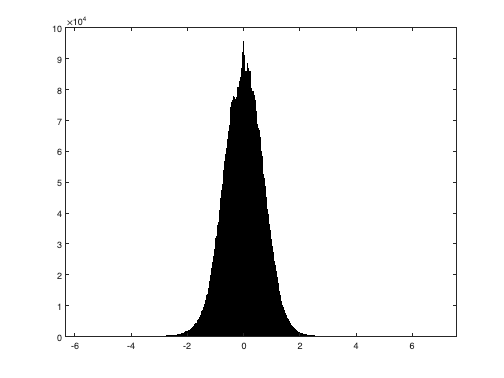

figure 
histogram(angleArray)

**Compute covariance matrix**

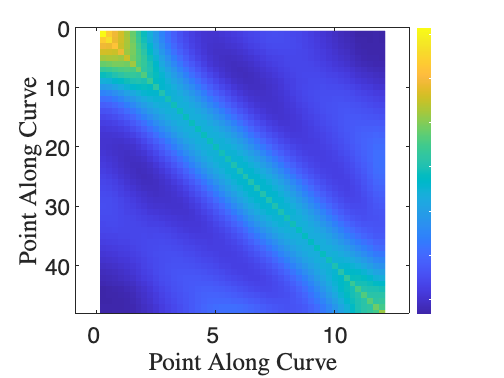

cov_ang_i = cov(angleArray,0,'omitrows');
h = figure; 
imagesc(cov_ang_i); % displays a matrix as a color map 
colormap(parula); % color scale selection 
cbar = colorbar; % insert colorbar
axis([0 size(cov_ang_i,1) 0 size(cov_ang_i,1)]);
set(gca,'XTickLabel',0:5:45);
xlabel('Point Along Curve',Interpreter='latex');
ylabel('Point Along Curve',Interpreter='latex');
axis equal;
cbar.Color = 'w';
set(gca,'FontSize',25);
% darkBackground(h);
set(gcf, 'inverthardcopy', 'off');
print("covarianceMatrixPoster",'-dpdf');

#### 3. Eigendecomposition 

[eigenvectors_i,D_i] = eig(cov_ang_i); 
eigenvalues_i = diag(D_i); 

[eigenvalues_i,ind_i] = sort(eigenvalues_i,'descend');    % check the eigenvalues 
eigenvectors_i = eigenvectors_i(:,ind_i);

sigma_i = sum(eigenvalues_i);
sigma_k_i = []; 

for k=1:size(eigenvectors_i,1)
    sigma_k_i = [sigma_k_i; sum(eigenvalues_i(1:k)/sigma_i)]; 
end 

Plot eigenvalues and percentage variance explained by k eigenvalues 

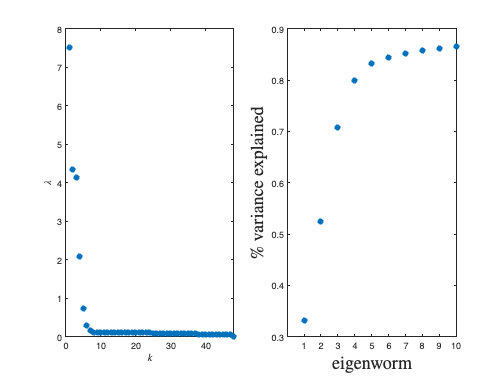

figure 
max_eigen = 10; 
subplot(1,2,1)  % eigenvalues
plot(eigenvalues_i,'.',MarkerSize=20)
xlabel('$k$',Interpreter='latex')
ylabel('$\lambda$',Interpreter='latex')

subplot(1,2,2) % percentage variance explained by k eigenvalues 
plot([1:max_eigen],sigma_k_i(1:max_eigen),'.',MarkerSize=20)
hold on 
yline(0.9,'-.')
xticks(1:max_eigen)
xlabel('eigenworm',Interpreter='latex',FontSize=20)
ylabel('$\%$ variance explained',Interpreter='latex',FontSize=20)

#### 4. Eigenprojection in time

Obtain individual work postural time series (select by individual index and stack posture in time) 

for j = 1:2     % loop through data set 
    name = sprintf('dataSet_%d', j);
    worm_index_joined_unique{j,1} = unique(trajData_struc.(name).worm_index_joined); % find unique worm index 

    for i = 1:size(worm_index_joined_unique{j},1)      % loop through worm indexes
        
        if j == 2
            k = size(worm_index_joined_unique{1},1) + i;   % k is the index for the newly created cells 
        else k = i;
        end

        x_temporaneo = []; y_temporaneo = []; 
        % find all index corresponding to worm index 
        index_row_worm_index{k,1} = find(trajData_struc.(name).worm_index_joined == worm_index_joined_unique{j}(i));

        % save x and y coordinates of postures belonging to worm index 
        x_temporaneo = skeleton_struc.(name)(1,:,index_row_worm_index{k});
        y_temporaneo = skeleton_struc.(name)(2,:,index_row_worm_index{k});
        
            % after reshaping 
        skeleton_x_worm_index{k,1} = reshape(x_temporaneo,49,[])'; 
        skeleton_y_worm_index{k,1} = reshape(y_temporaneo,49,[])'; 
        
        % compute angle array for all worms indexes 
        angle_posture_worm_index{k,1} = makeAngleArray(skeleton_x_worm_index{i},skeleton_y_worm_index{i}); 
    end 
end 

for i=1:size(worm_index_joined_unique{j},1)
    angle_posture_worm_index{i} = angle_posture_worm_index{i}(all(~isnan(angle_posture_worm_index{i}),2),:);      % clean all nan values 
end  

clear projection_worm_index
max_eigen = 4; 
for j = 1:2 % loop through the two data sets 
    for i = 1:size(worm_index_joined_unique{j},1)
        if j == 2
            r = size(worm_index_joined_unique{1},1) + i;   % r is the index for the newly created cells 
        else r = i;

        end
        for k=1:max_eigen
            projection_worm_index{r,1}{k,1} = angle_posture_worm_index{i}.*eigenvectors_i(:,k); % FIX THIS!!! Dim expected 1xT
        end 
    end 
end 

Wavelet Transform 

clear sig95
xlim = [1 2939];  % plotting range
dt = 1;
pad = 1;      % pad the time series with zeroes (recommended)
dj = 0.04;    % this will do 4 sub-octaves per octave (factor for scale averaging) 
s0 = 2*dt;    % this says start at a scale of 6 months
j1 = 1/dj;    % this says do 7 powers-of-two with dj sub-octaves each
lag1 = 0.72;  % lag-1 autocorrelation for red noise background
mother = 'Morlet';

for i = 1:max_eigen     % loop through eigenvectors 
    for j=1:size(angle_posture_worm_index,1)    % loop through all worms 
        % estimate angles 
            % done in previous cells: ang_skel_divided
        % estimate modes 
            % done in previous cells: eigenvectors and eigenvalues 
        % compute projections 
            % done in previous cells:
        
        
        % wavelet transform 
        clear sig95
        xlim = [1 size(angle_posture_worm_index{j}(1:end,:),1)];  % plotting range
        sst = projection_worm_index{j}{i};
        sst(find(isnan(sst))) = 0; 
        variance = std(sst)^2;
        sst = (sst - mean(sst))/sqrt(variance);
        
        
        % Wavelet transform:
        [wave,period,scale,coi] = wavelet(sst,dt,pad,dj,s0,j1,mother);
        power{j,:} = (abs(wave)).^2 ;        % compute wavelet power spectrum
    end 
end 

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each
element of the matrix individually, use POWER (.^) for elementwise power.


power_mat = []; 
for i=1:size(power,1)
    power_mat = [power_mat power{i}]; 
end 

feature_vector = [power_mat; worm_direc_divided_binary_mat']; 
feature_vector = feature_vector(:,all(~isnan(feature_vector)));   % delete all nan values 

## **Embedding + PDF**

### **tSNE**

Look into tSNE hyperparameters

tic 
    rng default % for reproducibility
    tSNE_feature_vec = tsne(feature_vector_norm','Algorithm','barneshut','distance','euclidean','NumDimensions',2);
    figure 
    gscatter(tSNE_feature_vec(:,1),tSNE_feature_vec(:,2));
toc

### **Probability density function: gaussian convolution (Gaussian-smoothing of UMAP output )**

use of function gkde2 info indcluded in folder gkde2. Returns both cdf and pdf 

space_density=gkde2(tSNE_feature_vec);

figure
gkde2(tSNE_feature_vec)

**Watershed Transform on smoothed embeded space **

water shed the reflection of the distribution in order to seperate max 

watershed_Space = watershed(-space_density.pdf);

Code modified from [link](https://gist.github.com/amroamroamro/6423064ee20ad1a3d4de93ad7d68d8f5)

% include tSNE points on plot 
OldRange = (100 - (-100)); 
NewRange = (50 - 0);
tSNE_feature_redim = (((tSNE_feature_vec - -100) * NewRange) / OldRange) + 0;

figure
surf(space_density.pdf, 'FaceAlpha',0.5, 'EdgeAlpha',0.25), hold on
warp(imfuse(space_density.pdf,watershed_Space,'blend'))
hold off, axis tight vis3d
colormap(flipud(hot(64))), colorbar
rotate3d on
hold on 
scater1=scatter(tSNE_feature_redim(:,1),tSNE_feature_redim(:,2),'.b');
alpha(scater1, 0.2);
hold off

% to check that watershed makes sense
figure
rgb = label2rgb(watershed_Space,'jet',[.5 .5 .5]);
warp(imfuse(rgb,space_density.pdf,"blend"))
hold on 
[M c] = contour(space_density.pdf);
c.LineWidth = 2;
colormap(gray)

**Find frames per group **

discretize position points in 50x50 bins 

index_cell_spaceDensity = cell(50,50);

for i=1:size(space_density.x,1)-1
    for j=1:size(space_density.y,1)-1
        index_cell_spaceDensity{i,j} = find((tSNE_feature_vec(:,1) >= space_density.x(i,j)) & (tSNE_feature_vec(:,1) <= space_density.x(i,j+1)) & (tSNE_feature_vec(:,2) >= space_density.y(i,j)) & (tSNE_feature_vec(:,2) <= space_density.y(i+1,j)));
    end 
end 

index_cell_spaceDensity_mat = cell2mat(index_cell_spaceDensity(~cellfun('isempty',index_cell_spaceDensity)));
size(index_cell_spaceDensity_mat) %66979, quindi ci sono tutte 

#### Assign group number to bin 

group_number = unique(watershed_Space);
groups = cell(size(group_number,1),1);

idx = cellfun(@isempty,index_cell_spaceDensity); % Find the indexes of empty cell
index_cell_spaceDensity(idx) = {0};   

for i=2:size(group_number,1) % don't care abous area 0 
    R = []; C = []; 
    [R C] = find(watershed_Space == group_number(i));
    for k=1:size(R,1)
        for s=1:size(C,1)
            groups{i,1} = [groups{i,1}; index_cell_spaceDensity{R(k),C(s)}];
        end 
    end
end 